**Détection du rythme cardiaque à l'aide d'une analyse spectrale**

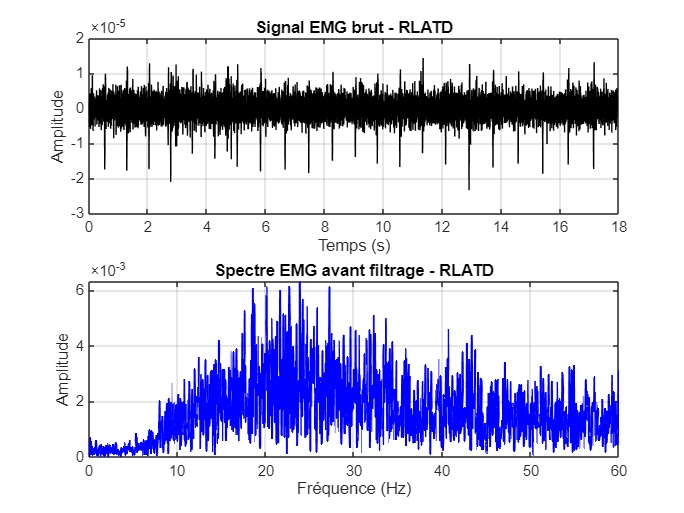

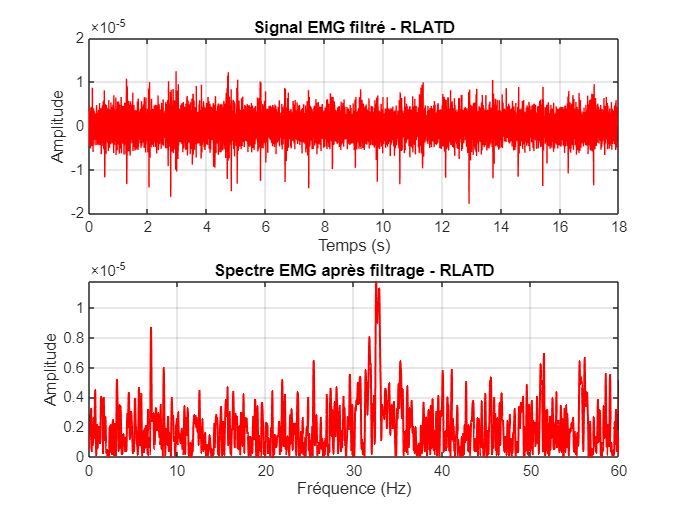

clc; clear all;  
addpath(genpath('C:\Users\Francalanci Hugo\Documents\MATLAB\Stage Sainte-Justine\HUG\btk'));

% Définition du sujet et du muscle ciblé
subject = 'TF02'; % Sujet spécifique
muscle_name = 'RLATD'; % Muscle contaminé par l’ECG
fs = 2000; % Fréquence d'échantillonnage

% Définition du fichier pour la tâche fonctionnelle choisie
selected_functional = 1; % Modifier selon la tâche souhaitée
fileName_functional = sprintf(['C:\\Users\\Francalanci Hugo\\Documents\\MATLAB\\Stage Sainte-Justine\\HUG\\Sujets\\%s\\' ...
    '%s-%s-20240101-PROTOCOL01-FUNCTIONAL%d-.c3d'], ...
    subject, subject, subject, selected_functional);

% Vérifier si le fichier existe
if exist(fileName_functional, 'file')
    c3dH_functional = btkReadAcquisition(fileName_functional);
    analogs_functional = btkGetAnalogs(c3dH_functional);
    
    if isfield(analogs_functional, muscle_name)
        % Extraction du signal EMG
        signal_raw = analogs_functional.(muscle_name);

        % -------- Affichage du signal brut --------
        figure;
        subplot(2,1,1);
        plot((0:length(signal_raw)-1)/fs, signal_raw, 'k');
        xlabel('Temps (s)'); ylabel('Amplitude');
        title(['Signal EMG brut - ', muscle_name]);
        grid on;
        
        % -------- Analyse spectrale (FFT) AVANT filtrage --------
        N_fft = 2^nextpow2(length(signal_raw));
        frequencies = (0:N_fft-1)*(fs/N_fft);
        EMG_fft = abs(fft(signal_raw, N_fft));

        subplot(2,1,2);
        plot(frequencies(1:N_fft/2), EMG_fft(1:N_fft/2), 'b', 'LineWidth', 1.2);
        xlabel('Fréquence (Hz)'); ylabel('Amplitude');
        title(['Spectre EMG avant filtrage - ', muscle_name]);
        xlim([0 60]);
        grid on;

        % -------- Filtrage du signal (Suppression du bruit cardiaque) --------
        [b, a] = butter(4, [15, 475] / (fs/2), 'bandpass'); % Passe-bande EMG
        [bh, ah] = butter(4, 20/(fs/2), 'high'); % Passe-haut 20 Hz
        
        signal_filtered = filtfilt(b, a, signal_raw); % Filtre passe-bande
        signal_filtered = filtfilt(bh, ah, signal_filtered); % Filtre passe-haut
        EMG_fft_filtered = sqrt(movmean(abs(signal_filtered).^2, 0.250));

        % -------- Affichage du signal filtré --------
        figure;
        subplot(2,1,1);
        plot((0:length(signal_filtered)-1)/fs, signal_filtered, 'r');
        xlabel('Temps (s)'); ylabel('Amplitude');
        title(['Signal EMG filtré - ', muscle_name]);
        grid on;

        % -------- Analyse spectrale (FFT) APRÈS filtrage --------
        subplot(2,1,2);
        plot(frequencies(1:N_fft/2), EMG_fft_filtered(1:N_fft/2), 'r', 'LineWidth', 1.2);
        xlabel('Fréquence (Hz)'); ylabel('Amplitude');
        title(['Spectre EMG après filtrage - ', muscle_name]);
        xlim([0 60]);
        grid on;

    else
        warning('Données EMG absentes pour %s - Sujet %s', muscle_name, subject);
    end
else
    warning('Fichier introuvable : %s', fileName_functional);
end